## PART 1: KINEMATICS

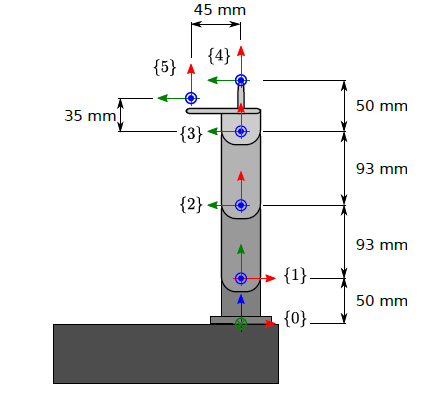

addpath('./src');

### Problem 1:

Find, by the use of Figure 1, the direct kinematic transformations, $$T_{4}^{0}$$ for the robot stylus, and $$T_{5}^{0}$$ for the robot camera, as function of all joint angles.

% Preliminary transformations

L01 = 50;
L12 = 93;
L23 = 93;
L34 = 50;
L45 = 45;
L35 = 35;

% % Uncomment for symbolic representation
syms theta0 theta1 theta2 theta3 

% from DH convention we get:

% {0} -> {1}
T01 = [cos(theta0), 0, sin(theta0), 0;
       sin(theta0), 0, -cos(theta0), 0;
       0, 1, 0, L01;
       0, 0, 0, 1];

% {1} -> {2}
T12 = [cos(theta1), -sin(theta1), 0, L12*cos(theta1);
       sin(theta1), cos(theta1), 0, L12*sin(theta1);
       0, 0, 1, 0;
       0, 0, 0, 1];

% {2} -> {3}
T23 = [cos(theta2), -sin(theta2), 0, L23*cos(theta2);
       sin(theta2), cos(theta2), 0, L23*sin(theta2);
       0, 0, 1, 0;
       0, 0, 0, 1];

% {3} -> {4}     
T34 = [cos(theta3), -sin(theta3), 0, L34*cos(theta3);
       sin(theta3), cos(theta3), 0, L34*sin(theta3);
       0, 0, 1, 0;
       0, 0, 0, 1];

% {3} -> {5}
T35 = [1, 0, 0, L35;
       0, 1, 0, L45;
       0, 0, 1, 0;
       0, 0, 0, 1];

% Transformation from {0} to {4}
T04 = simplify(T01*T12*T23*T34)

$$T04 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{3}\,\cos\left(\theta_{0}\right) & -\sigma_{1}\,\cos\left(\theta_{0}\right) & \sin\left(\theta_{0}\right) & \cos\left(\theta_{0}\right)\,\sigma_{2}\\ \sigma_{3}\,\sin\left(\theta_{0}\right) & -\sigma_{1}\,\sin\left(\theta_{0}\right) & -\cos\left(\theta_{0}\right) & \sin\left(\theta_{0}\right)\,\sigma_{2}\\ \sigma_{1} & \sigma_{3} & 0 & 50\,\sigma_{1}+93\,\sin\left(\theta_{1}+\theta_{2}\right)+93\,\sin\left(\theta_{1}\right)+50\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{2}=50\,\sigma_{3}+93\,\cos\left(\theta_{1}+\theta_{2}\right)+93\,\cos\left(\theta_{1}\right)\\ \sigma_{3}=\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) \end{array}$$


% Transformation from {0} to {5}
T05 = simplify(T01*T12*T23*T35)

$$T05 = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{0}\right) & -\sin\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{0}\right) & \sin\left(\theta_{0}\right) & \cos\left(\theta_{0}\right)\,\sigma_{1}\\ \cos\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{0}\right) & -\sin\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{0}\right) & -\cos\left(\theta_{0}\right) & \sin\left(\theta_{0}\right)\,\sigma_{1}\\ \sin\left(\theta_{1}+\theta_{2}\right) & \cos\left(\theta_{1}+\theta_{2}\right) & 0 & 93\,\sin\left(\theta_{1}\right)+\sqrt{18409}\,\cos\left(\theta_{1}+\theta_{2}-\mathrm{atan}\left(\frac{128}{45}\right)\right)+50\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=128\,\cos\left(\theta_{1}+\theta_{2}\right)-45\,\sin\left(\theta_{1}+\theta_{2}\right)+93\,\cos\left(\theta_{1}\right) \end{array}$$

### Problem 2: 

Determine the inverse kinematic transformation


$$$q = [q_1, q_2, q_3, q_4]^T = f(x_{4}^0, o_{4}^0)$$$


where $$x_{4}^{0}$$ are the first 3 components of the first column of $$T_{4}^{0}$$ , and $$o_{4}^{0}$$ are the first 3 components of the last column of $$T_{4}^{0}$$ , respectively. Satisfy all position components in $$o_{4}^{0}$$ and as many components in $$x_{4}^{0}$$ as possible.

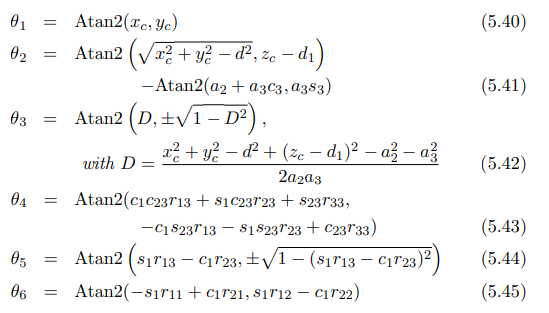

xc = 100;
yc = 100;
zc = 100;


d = L12; % or 23
D = (xc^2 + yc^2 - d^2 + (zc - L01)^2 - L12^2 - L23^2)/(2*L12*L23)

D = -0.1993


% create r

R01 = [1 0 0 0;
       0 cos(theta0) -sin(theta0) 0;
       0 sin(theta0) cos(theta0) 0;
       0 0 0 1];
% {1} -> {2}
R12 = [cos(theta1) -sin(theta1) 0 0;
       sin(theta1) cos(theta1) 0 0;
       0 0 1 0;
       0 0 0 1];

R = R01*R12;



theta0 = atan2(xc,yc);

theta2 = atan2(D, sqrt(1-D^2));

theta1 = atan2(sqrt(xc^2 + yc^2 - d^2) , zc - L01) - atan2(L12+L23*cos(theta3), L23*sin(theta3));

R01 = [1 0 0 0;
       0 cos(theta0) -sin(theta0) 0;
       0 sin(theta0) cos(theta0) 0;
       0 0 0 1];
% {1} -> {2}
R12 = [cos(theta1) -sin(theta1) 0 0;
       sin(theta1) cos(theta1) 0 0;
       0 0 1 0;
       0 0 0 1];

R = R01*R12;





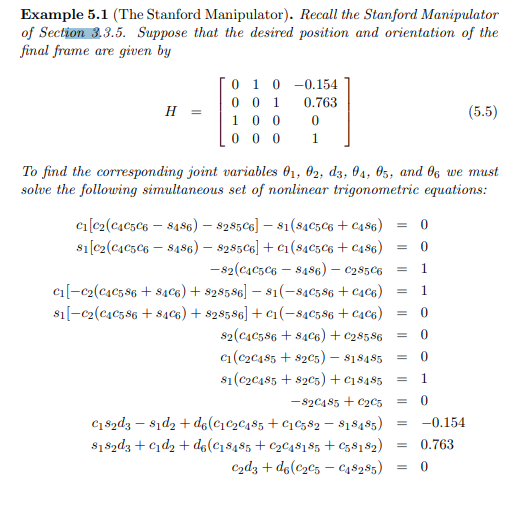

Next up we need to set up and solve this mess of equations.

We have the equations for T04 in the original matrixes calculated from the symbolic variables and we can derive the absolute value of H from the theta values calculated from the grapically derived equations.

## **Problem 3:**

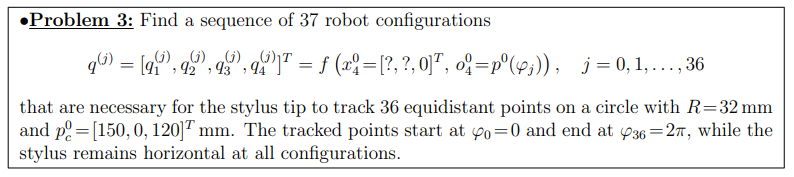

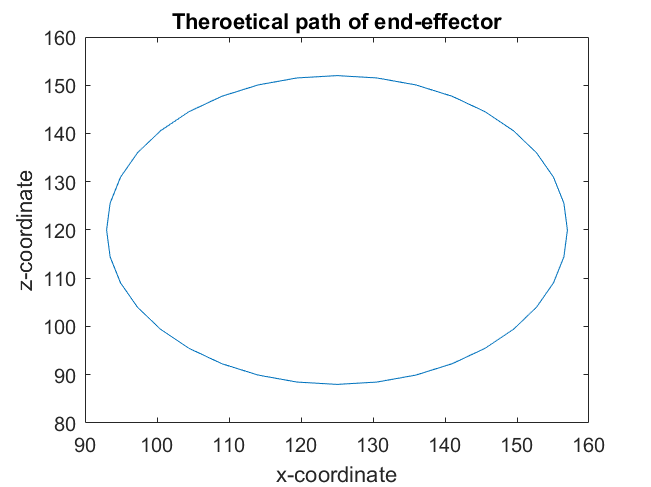


% origin of the circle to be traced
xc = 125;
yc = 0;
zc = 120;

angles = 0:2*pi/36:2*pi; % this is the phi angle reported in the previous line


dx = cos(angles)*32;
dz = sin(angles)*32;

x = xc + dx;
y = yc*ones(1,length(angles));
z = zc + dz;

figure
plot(x,z)
title("Theroetical path of end-effector")
xlabel("x-coordinate")
ylabel("z-coordinate")

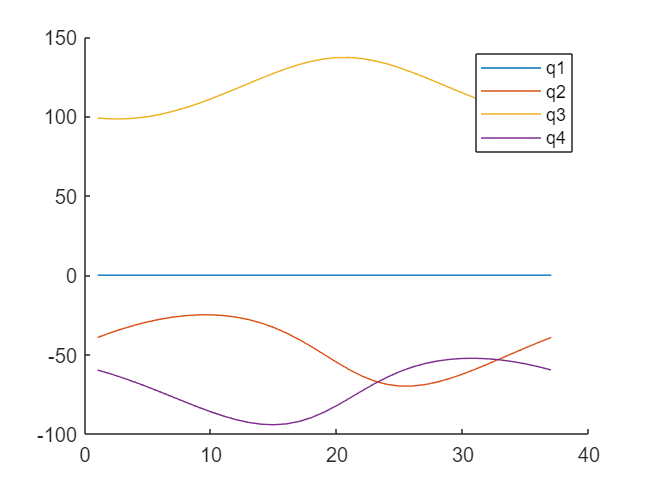



% transform coordinates to angles
% Stylus always parallel to the ground
x04 = [0.97, 0.2, 0];
pos = [x; y; z];

for p = 1:size(pos,2)
    [t1(p),t2(p),t3(p),t4(p)] = invKinematics(x04, pos(:,p));
end

figure
hold on
plot(t1)
plot(t2)
plot(t3)
plot(t4)
legend(["q1","q2","q3","q4"])


pos2 = zeros(4,37);
for i = 1:size(pos,2)
    [T01, T12, T23, T34, T35] = T_finder(t1(i),t2(i),t3(i),t4(i));
    T04 = T01*T12*T23*T34;
    pos2(:,i) = T04*[0,0,0,1]';
end
pos2

pos2 =   168.8465  168.4029  167.0874  164.9459  162.0534  158.5112  154.4438  149.9941  145.3182  140.5787  135.9372  131.5460  127.5403  124.0304  121.0975  118.7927  117.1415  116.1514  115.8217  116.1514  117.1415  118.7927  121.0975  124.0304  127.5403  131.5460  135.9372  140.5787  145.3182  149.9941  154.4438  158.5112  162.0534  164.9459  167.0874  168.4029  168.8465
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   71.5000   77.0567   82.4446   87.5000   92.0692   96.0134   99.2128  101.5702  103.0138  103.5000  103.0138  101.5702   99.2128   96.0134   92.0692   87.5000   82.4446   77.0567   71.5000   65.9433   60.5554   55.5000   50.9308   46.9866   43.7872 

pos

pos =   157.0000  156.5138  155.0702  152.7128  149.5134  145.5692  141.0000  135.9446  130.5567  125.0000  119.4433  114.0554  109.0000  104.4308  100.4866   97.2872   94.9298   93.4862   93.0000   93.4862   94.9298   97.2872  100.4866  104.4308  109.0000  114.0554  119.4433  125.0000  130.5567  135.9446  141.0000  145.5692  149.5134  152.7128  155.0702  156.5138  157.0000
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
  120.0000  125.5567  130.9446  136.0000  140.5692  144.5134  147.7128  150.0702  151.5138  152.0000  151.5138  150.0702  147.7128  144.5134  140.5692  136.0000  130.9446  125.5567  120.0000  114.4433  109.0554  104.0000   99.4308   95.4866   92.2872  

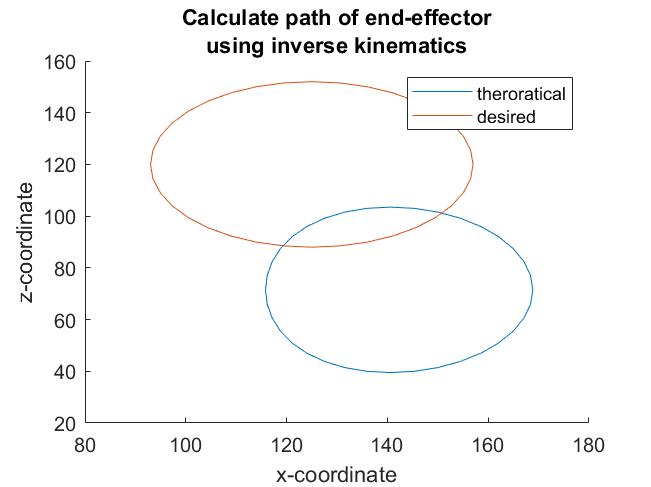


figure
hold on
plot(pos2(1,:),pos2(3,:))
plot(pos(1,:),pos(3,:))
title(["Calculate path of end-effector", "using inverse kinematics"])
xlabel("x-coordinate")
ylabel("z-coordinate")
legend(["theroratical", "desired"])



%t4 = ones(1,length(x)).*(pi-t1-t2-t3) % ensures horizontality

% R01 = [1 0 0 0;
%        0 cos(t1) -sin(t1) 0;
%        0 sin(t1) cos(t1) 0;
%        0 0 0 1];

% % {1} -> {2}
% R12 = [cos(t2) -sin(t2) 0 0;
%        sin(t2) cos(t2) 0 0;
%        0 0 1 0;
%        0 0 0 1];
% 

% R = R01*R12;
% 
% 
% t4 =atan2(cos(t1).*cos(t2+t3).*R(1,3) + sin(t1).*cos(t2+t3).*R(2,3) + sin(t2+t3).*R(3,3), -cos(t1).*sin(t2+t3).*R(1,3) - sin(t1).*sin(t2+t3).*R(2,3)+cos(t2+t3).*R(3,3));


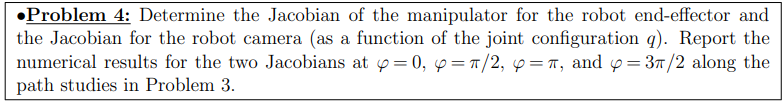



% if you need help figuring out the angles contact Palli


phi = [0 pi/2 pi 3*pi/2];

dy = cos(phi)*16;
dz = sin(phi)*16;

x = zeros(1,length(phi));
y = yc + dy;
z = zc + dz;

q1 = ones(1,4);
q2 = ones(1,4);
q3 = ones(1,4);
q4 = ones(1,4);



% Please don't write into t1,t2t3,t4
% using in 6 & 7
%[t1,t2,t3] = theta(x,y,z);
%t4 = ones(1,length(x)).*(pi-t1-t2-t3);



x04 = [0.97, 0.2, 0];
pos = [x; y; z];

for p = 1:size(pos,2)
    [q1(p),q2(p),q3(p),q4(p)] = invKinematics(x04, pos(:,p));
end

for i = 1:length(q1)
   [T01, T12, T23, T34, T35] = T_finder(q1(i),q2(i),q3(i),q4(i));

   % use T35 as the problem statement asks for the camera, not the stylus

   disp("Jacobian stylus")
   disp(phi(i))
   J = Jacob(T01, T12, T23, T34)

   disp("Jacobian camera")
   disp(phi(i))
   J = Jacob(T01, T12, T23, T35)
end

Jacobian stylus


     0



J =    -2.9710  -21.4919  -92.9586         0
  108.3416   -0.5894   -2.5492         0
         0  108.3824   48.9040   50.0000
         0    0.0274    0.0274    0.0274
         0   -0.9996   -0.9996   -0.9996
    1.0000         0         0         0


Jacobian camera


     0



J =    -0.3556  -55.9462 -127.4129  -34.4543
   12.9681   -1.5342   -3.4940   -0.9448
         0   12.9730  -46.5053  -45.4093
         0    0.0274    0.0274    0.0274
         0   -0.9996   -0.9996   -0.9996
    1.0000         0         0         0


Jacobian stylus


    1.5708



J =    -3.2508  -37.4859  -92.7591         0
  118.5448   -1.0280   -2.5437         0
         0  118.5894   43.8125   50.0000
         0    0.0274    0.0274    0.0274
         0   -0.9996   -0.9996   -0.9996
    1.0000         0         0         0


Jacobian camera


    1.5708



J =    -0.5855  -69.4024 -124.6756  -31.9165
   21.3524   -1.9032   -3.4189   -0.8752
         0   21.3604  -53.4164  -47.2289
         0    0.0274    0.0274    0.0274
         0   -0.9996   -0.9996   -0.9996
    1.0000         0         0         0


Jacobian stylus


    3.1416



J =     3.5828  -21.4919  -91.0131         0
  130.6509    0.5894    2.4958         0
         0  130.7001   68.9573   50.0000
         0   -0.0274   -0.0274   -0.0274
         0   -0.9996   -0.9996   -0.9996
    1.0000         0         0         0


Jacobian camera


    3.1416



J =     1.2001  -64.9136 -134.4348  -43.4217
   43.7629    1.7801    3.6865    1.1907
         0   43.7794  -17.9634  -36.9207
         0   -0.0274   -0.0274   -0.0274
         0   -0.9996   -0.9996   -0.9996
    1.0000         0         0         0


Jacobian stylus


    4.7124



J =     3.2508   -5.4979  -88.8422         0
  118.5448    0.1508    2.4363         0
         0  118.5894   77.3885   50.0000
         0   -0.0274   -0.0274   -0.0274
         0   -0.9996   -0.9996   -0.9996
    1.0000         0         0         0


Jacobian camera


    4.7124



J =     0.9839  -52.1807 -135.5249  -46.6828
   35.8791    1.4309    3.7164    1.2802
         0   35.8925   -5.3083  -32.6968
         0   -0.0274   -0.0274   -0.0274
         0   -0.9996   -0.9996   -0.9996
    1.0000         0         0         0


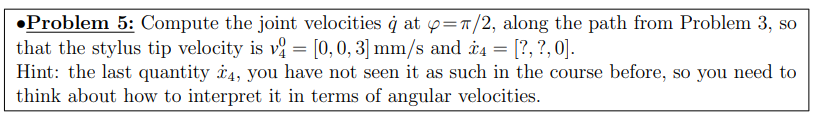

%[T01_old, T12_old, T23_old, T34_old, T35_old] = T_finder(t1(1),t2(1),t3(1),t4(1));
clc
% Parameters to tune
x1 = 0;
x2 = 0;

Vc = [0;0;3;x1;x2;0];

for i = 9
    
    [T01, T12, T23, T34, T35] = T_finder(t1(i),t2(i),t3(i),t4(i));

    q = [t1(i),t2(i),t3(i),t4(i)]';
    J = Jacob(T01,T12,T23,T34);

    qA_dot = inv(J'*J)*J'*Vc;


    T04=T01*T12*T23*T34;
    T03=T01*T12*T23;
    T02=T01*T12;
    
    o4 = [T04(1,4) T04(2,4) T04(3,4)];

    k1 = [T01(1,4); T01(2,4); T01(3,4)];
    k1 = k1/norm(k1);
    k2 = [T12(1,4); T12(2,4); T12(3,4)];
    k2 = k2/norm(k2);
    k3 = [T23(1,4); T23(2,4); T23(3,4)];
    k3 = k3/norm(k3);
    k4 = [T34(1,4); T34(2,4); T34(3,4)];
    k4 = k4/norm(k4);

    w01 = qA_dot(1)*k1;
    w12 = qA_dot(2)*k2;
    w23 = qA_dot(3)*k3;
    w34 = qA_dot(4)*k4;

    R01 = [T01(1,1) T01(1,2) T01(1,3);T01(2,1) T01(2,2) T01(2,3);T01(3,1) T01(3,2) T01(3,3)];
    R02 = [T02(1,1) T02(1,2) T02(1,3);T02(2,1) T02(2,2) T02(2,3);T02(3,1) T02(3,2) T02(3,3)];
    R03 = [T03(1,1) T03(1,2) T03(1,3);T03(2,1) T03(2,2) T03(2,3);T03(3,1) T03(3,2) T03(3,3)];
    R04 = [T04(1,1) T04(1,2) T04(1,3);T04(2,1) T04(2,2) T04(2,3);T04(3,1) T04(3,2) T04(3,3)];

    w04 = w01 + R01*w12 + R02*w23 + R03*w34;

    % want 0 0 3
    v04 = cross(w04,o4)
    

end

v04 =          0   -6.2963         0


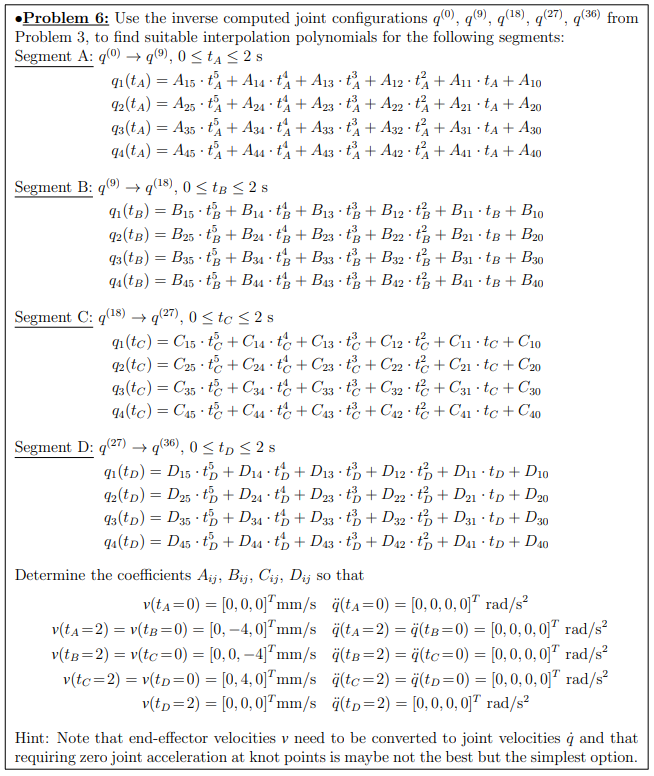

%load("t1.mat");
%load("t2.mat");
%load("t3.mat");
%load("t4.mat");
tIN = 0;%start point of each time interval
tOUT = 2;%end point of each time interval

V0 = [0;0;0;0;0;0];
VA = [0;-4;0;0;0;0];
VB = [0;0;-4;0;0;0];
VC = [0;4;0;0;0;0];
VD = [0;0;0;0;0;0];

q0 = [t1(1),t2(1),t3(1),t4(1)]';
qA = [t1(10),t2(10),t3(10),t4(10)]';
qB = [t1(19),t2(19),t3(19),t4(19)]';
qC = [t1(28),t2(28),t3(28),t4(28)]';
qD = [t1(37),t2(37),t3(37),t4(37)]';

%vectors of end-effffector velocities v 
[T01,T12,T23,T34,T35] = T_finder(t1(1),t2(1),t3(1),t4(1));
J0 = Jacob(T01,T12,T23,T34);

[T01,T12,T23,T34,T35] = T_finder(t1(10),t2(10),t3(10),t4(10));
JA = Jacob(T01,T12,T23,T34);

[T01,T12,T23,T34,T35] = T_finder(t1(19),t2(19),t3(19),t4(19));
JB = Jacob(T01,T12,T23,T34);

[T01,T12,T23,T34,T35] = T_finder(t1(28),t2(28),t3(28),t4(28));
JC = Jacob(T01,T12,T23,T34);

[T01,T12,T23,T34,T35] = T_finder(t1(37),t2(37),t3(37),t4(37));
JD = Jacob(T01,T12,T23,T34);


%jaconbian matrix for calculating joint velocities ˙q
q0_dot = [0, 0, 0, 0]';
qA_dot = inv(JA'*JA)*JA'*VA;
qB_dot = inv(JB'*JB)*JB'*VB;
qC_dot = inv(JC'*JC)*JC'*VC;
qD_dot = inv(JD'*JD)*JD'*VD;

%Calculation of joint velocities ˙q
ain = [0,0,0,0]';
aout = [0,0,0,0]';
%acceleration is always 0

A = getConstant(tIN,tOUT,q0,qA,q0_dot,qA_dot,ain,aout)

A =          0  -39.2546   99.0176  -59.7630
    0.0000         0   -0.0000         0
         0         0         0         0
    0.0285   17.8319   15.1209  -32.9528
   -0.0249  -13.3739  -11.3407   24.7146
    0.0053    2.6748    2.2681   -4.9429


B = getConstant(tIN,tOUT,qA,qB,qA_dot,qB_dot,ain,aout)

B =          0  -24.9891  111.1143  -86.1252
   -0.0285   -0.0000   -0.0000    0.0000
         0         0         0         0
    0.0427  -31.2698   31.4520   -0.1822
   -0.0285   23.4446  -23.5872    0.1426
    0.0053   -4.6881    4.7173   -0.0291


C = getConstant(tIN,tOUT,qB,qC,qB_dot,qC_dot,ain,aout)

C =          0  -50.0546  136.2874  -86.2328
         0   -0.0621    0.0144    0.0477
         0         0         0         0
   -0.0285  -21.4083  -18.7722   40.1805
    0.0249   16.0640   14.0774  -30.1413
   -0.0053   -3.2136   -2.8153    6.0289


D = getConstant(tIN,tOUT,qC,qD,qC_dot,qD_dot,ain,aout)

D =          0  -67.2557  121.2869  -54.0311
    0.0285    0.0000   -0.0000    0.0000
         0         0         0         0
   -0.0427   35.0014  -27.8366   -7.1649
    0.0285  -26.2511   20.8774    5.3736
   -0.0053    5.2502   -4.1755   -1.0747



% The constant for Ani is A(n,i) where n is the joint number and i is the
% constant number



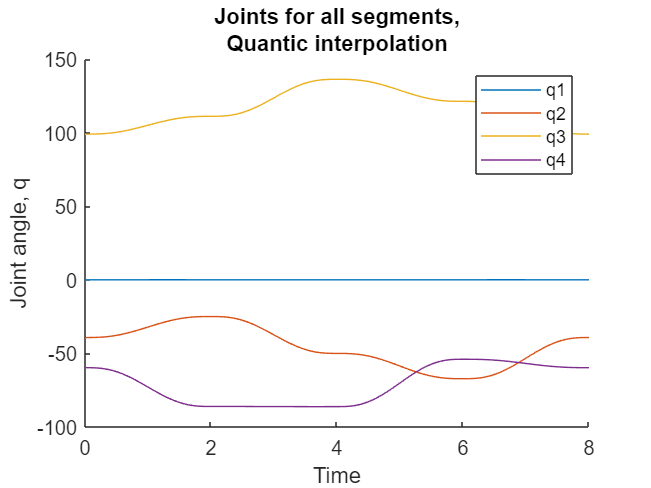

t = 0:0.01:2;
q1A = A(1,1) + A(2,1).*t + A(3,1).*t.^2 + A(4,1).*t.^3 + A(5,1).*t.^4 + A(6,1).*t.^5;
q2A = A(1,2) + A(2,2).*t + A(3,2).*t.^2 + A(4,2).*t.^3 + A(5,2).*t.^4 + A(6,2).*t.^5;
q3A = A(1,3) + A(2,3).*t + A(3,3).*t.^2 + A(4,3).*t.^3 + A(5,3).*t.^4 + A(6,3).*t.^5;
q4A = A(1,4) + A(2,4).*t + A(3,4).*t.^2 + A(4,4).*t.^3 + A(5,4).*t.^4 + A(6,4).*t.^5;

q1B = B(1,1) + B(2,1).*t + B(3,1).*t.^2 + B(4,1).*t.^3 + B(5,1).*t.^4 + B(6,1).*t.^5;
q2B = B(1,2) + B(2,2).*t + B(3,2).*t.^2 + B(4,2).*t.^3 + B(5,2).*t.^4 + B(6,2).*t.^5;
q3B = B(1,3) + B(2,3).*t + B(3,3).*t.^2 + B(4,3).*t.^3 + B(5,3).*t.^4 + B(6,3).*t.^5;
q4B = B(1,4) + B(2,4).*t + B(3,4).*t.^2 + B(4,4).*t.^3 + B(5,4).*t.^4 + B(6,4).*t.^5;

q1C = C(1,1) + C(2,1).*t + C(3,1).*t.^2 + C(4,1).*t.^3 + C(5,1).*t.^4 + C(6,1).*t.^5;
q2C = C(1,2) + C(2,2).*t + C(3,2).*t.^2 + C(4,2).*t.^3 + C(5,2).*t.^4 + C(6,2).*t.^5;
q3C = C(1,3) + C(2,3).*t + C(3,3).*t.^2 + C(4,3).*t.^3 + C(5,3).*t.^4 + C(6,3).*t.^5;
q4C = C(1,4) + C(2,4).*t + C(3,4).*t.^2 + C(4,4).*t.^3 + C(5,4).*t.^4 + C(6,4).*t.^5;

q1D = D(1,1) + D(2,1).*t + D(3,1).*t.^2 + D(4,1).*t.^3 + D(5,1).*t.^4 + D(6,1).*t.^5;
q2D = D(1,2) + D(2,2).*t + D(3,2).*t.^2 + D(4,2).*t.^3 + D(5,2).*t.^4 + D(6,2).*t.^5;
q3D = D(1,3) + D(2,3).*t + D(3,3).*t.^2 + D(4,3).*t.^3 + D(5,3).*t.^4 + D(6,3).*t.^5;
q4D = D(1,4) + D(2,4).*t + D(3,4).*t.^2 + D(4,4).*t.^3 + D(5,4).*t.^4 + D(6,4).*t.^5;

% combine the joint angles 
q1 = [q1A, q1B(2:end), q1C(2:end), q1D(2:end)];
q2 = [q2A, q2B(2:end), q2C(2:end), q2D(2:end)];
q3 = [q3A, q3B(2:end), q3C(2:end), q3D(2:end)];
q4 = [q4A, q4B(2:end), q4C(2:end), q4D(2:end)];
t_all = 0:0.01:8;

figure 
hold on
plot(t_all,q1)
plot(t_all,q2)
plot(t_all,q3)
plot(t_all,q4)
xlabel("Time")
ylabel("Joint angle, q")
title(["Joints for all segments,","Quantic interpolation"])
legend(["q1","q2","q3","q4"])

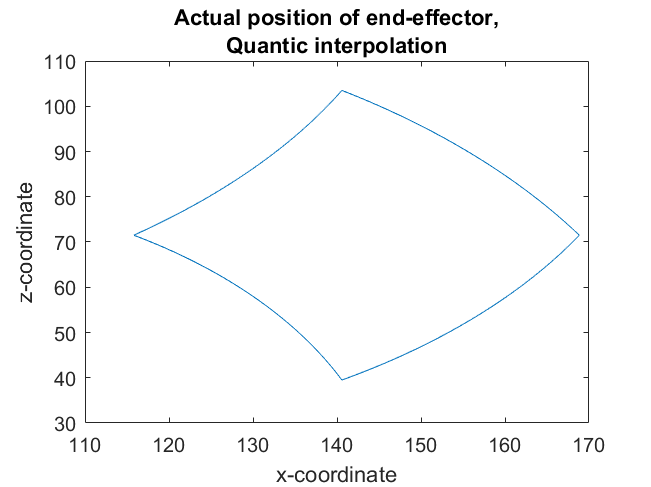



pos = zeros(4,length(q1));
for i = 1:length(pos)
    [T01, T12, T23, T34, T35] = T_finder(q1(i),q2(i),q3(i),q4(i));
    T04 = T01*T12*T23*T34;
    pos(:,i) = T04*[0,0,0,1]'; 
end

figure
plot(pos(1,:),pos(3,:))
title(["Actual position of end-effector,","Quantic interpolation"])
xlabel("x-coordinate")
ylabel("z-coordinate")

## Cubic interpolation


A = getConstantCubic(tIN,tOUT,q0,qA,q0_dot,qA_dot,ain,aout)

A =          0  -39.2546   99.0176  -59.7630
         0         0         0         0
    0.0142   10.6991    9.0725  -19.7717
   -0.0071   -3.5664   -3.0242    6.5906


B = getConstantCubic(tIN,tOUT,qA,qB,qA_dot,qB_dot,ain,aout)

B =          0  -24.9891  111.1143  -86.1252
   -0.0285         0         0         0
    0.0285  -18.7681   18.8726   -0.1045
   -0.0071    6.2509   -6.2897    0.0388


C = getConstantCubic(tIN,tOUT,qB,qC,qB_dot,qC_dot,ain,aout)

C =          0  -50.0546  136.2874  -86.2328
         0   -0.0621    0.0144    0.0477
   -0.0142  -12.8387  -11.2648   24.1035
    0.0071    4.2848    3.7537   -8.0385


D = getConstantCubic(tIN,tOUT,qC,qD,qC_dot,qD_dot,ain,aout)

D =          0  -67.2557  121.2869  -54.0311
    0.0285         0         0         0
   -0.0285   21.0009  -16.7019   -4.2989
    0.0071   -7.0003    5.5673    1.4330


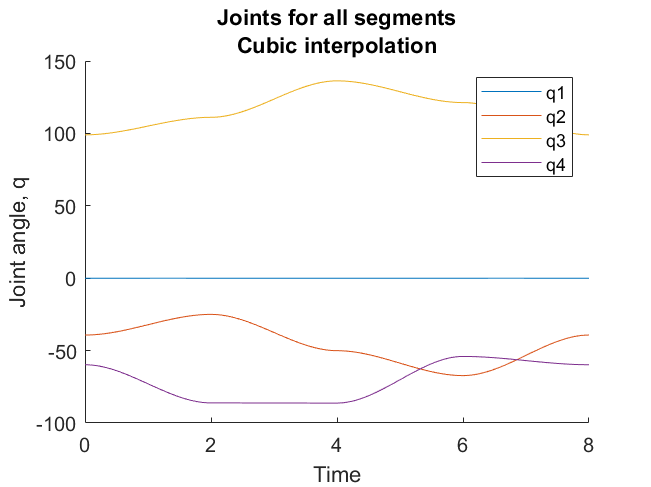

t = 0:0.01:2;
q1A = A(1,1) + A(2,1).*t + A(3,1).*t.^2 + A(4,1).*t.^3;
q2A = A(1,2) + A(2,2).*t + A(3,2).*t.^2 + A(4,2).*t.^3;
q3A = A(1,3) + A(2,3).*t + A(3,3).*t.^2 + A(4,3).*t.^3;
q4A = A(1,4) + A(2,4).*t + A(3,4).*t.^2 + A(4,4).*t.^3;

q1B = B(1,1) + B(2,1).*t + B(3,1).*t.^2 + B(4,1).*t.^3;
q2B = B(1,2) + B(2,2).*t + B(3,2).*t.^2 + B(4,2).*t.^3;
q3B = B(1,3) + B(2,3).*t + B(3,3).*t.^2 + B(4,3).*t.^3;
q4B = B(1,4) + B(2,4).*t + B(3,4).*t.^2 + B(4,4).*t.^3;

q1C = C(1,1) + C(2,1).*t + C(3,1).*t.^2 + C(4,1).*t.^3;
q2C = C(1,2) + C(2,2).*t + C(3,2).*t.^2 + C(4,2).*t.^3;
q3C = C(1,3) + C(2,3).*t + C(3,3).*t.^2 + C(4,3).*t.^3;
q4C = C(1,4) + C(2,4).*t + C(3,4).*t.^2 + C(4,4).*t.^3;

q1D = D(1,1) + D(2,1).*t + D(3,1).*t.^2 + D(4,1).*t.^3;
q2D = D(1,2) + D(2,2).*t + D(3,2).*t.^2 + D(4,2).*t.^3;
q3D = D(1,3) + D(2,3).*t + D(3,3).*t.^2 + D(4,3).*t.^3;
q4D = D(1,4) + D(2,4).*t + D(3,4).*t.^2 + D(4,4).*t.^3;

% combine the joint angles 
q1 = [q1A, q1B(2:end), q1C(2:end), q1D(2:end)];
q2 = [q2A, q2B(2:end), q2C(2:end), q2D(2:end)];
q3 = [q3A, q3B(2:end), q3C(2:end), q3D(2:end)];
q4 = [q4A, q4B(2:end), q4C(2:end), q4D(2:end)];
t_all = 0:0.01:8;

figure 
hold on
plot(t_all,q1)
plot(t_all,q2)
plot(t_all,q3)
plot(t_all,q4)
xlabel("Time")
ylabel("Joint angle, q")
title(["Joints for all segments","Cubic interpolation"])
legend(["q1","q2","q3","q4"])

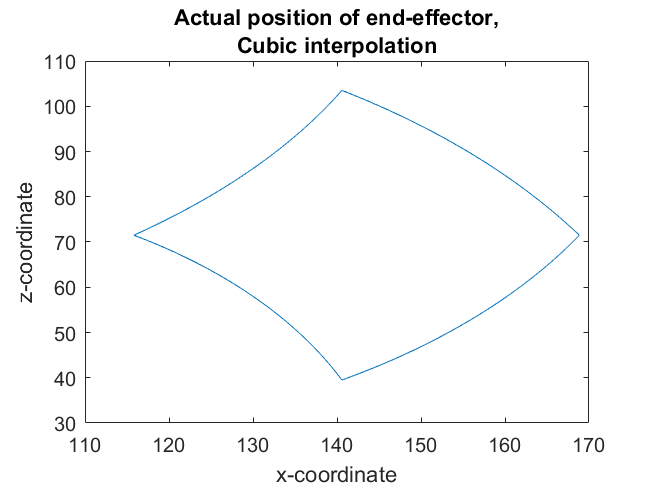



pos = zeros(4,length(q1));
for i = 1:length(pos)
    [T01, T12, T23, T34, T35] = T_finder(q1(i),q2(i),q3(i),q4(i));
    T04 = T01*T12*T23*T34;
    pos(:,i) = T04*[0,0,0,1]'; 
end

figure
plot(pos(1,:),pos(3,:))
title(["Actual position of end-effector,", "Cubic interpolation"])
xlabel("x-coordinate")
ylabel("z-coordinate")

## double the knot points

% calculate the approrate speeds at pi/4, 3pi/4 and 5pi/4 and 7pi/4
w = 4*sin(pi/2)/32e-3;
u = 2*pi/37; % angle change at each point
%angles in t are not exactly for pi/4,.....

q0A = [t1(5),t2(5),t3(5),t4(5)]';
q0B = [t1(15),t2(15),t3(15),t4(15)]';
q0C = [t1(23),t2(23),t3(23),t4(23)]';
q0D = [t1(33),t2(33),t3(33),t4(33)]';

V0A = [0;w*sin(u*5)*32e-3;w*cos(u*5)*32e-3;0;0;0];
V0B = [0;w*sin(u*15)*32e-3;w*cos(u*15)*32e-3;0;0;0];
V0C = [0;w*sin(u*23)*32e-3;w*cos(u*23)*32e-3;0;0;0];
V0D = [0;w*sin(u*33)*32e-3;w*cos(u*33)*32e-3;0;0;0];

[T01,T12,T23,T34,T35] = T_finder(t1(5),t2(5),t3(5),t4(5));
J0A = Jacob(T01,T12,T23,T34);

[T01,T12,T23,T34,T35] = T_finder(t1(15),t2(15),t3(15),t4(15));
J0B = Jacob(T01,T12,T23,T34);

[T01,T12,T23,T34,T35] = T_finder(t1(23),t2(23),t3(23),t4(23));
J0C = Jacob(T01,T12,T23,T34);

[T01,T12,T23,T34,T35] = T_finder(t1(33),t2(33),t3(33),t4(33));
J0D = Jacob(T01,T12,T23,T34);

q0A_dot = (J0A'*J0A)\J0A'*V0A;
q0B_dot = (J0B'*J0B)\J0B'*V0B;
q0C_dot = (J0C'*J0C)\J0C'*V0C;
q0D_dot = (J0D'*J0D)\J0D'*V0D;


A0 = getConstant(tIN,tOUT,q0,q0A,q0_dot,q0A_dot,ain,aout)

A0 =          0  -39.2546   99.0176  -59.7630
    0.0000   -0.0000         0   -0.0000
         0         0         0         0
   -0.0185   12.3299    1.1085  -13.4384
    0.0162   -9.2441   -0.8330   10.0770
   -0.0035    1.8485    0.1668   -2.0152


A = getConstant(tIN,tOUT,q0A,qA,q0A_dot,qA_dot,ain,aout)

A =          0  -29.3689   99.8939  -70.5250
    0.0185    0.0272   -0.0130   -0.0141
         0         0         0         0
    0.0007    5.4340   14.0450  -19.4790
   -0.0064   -4.0789  -10.5321   14.6110
    0.0019    0.8161    2.1063   -2.9224


B0 = getConstant(tIN,tOUT,qA,q0B,qA_dot,q0B_dot,ain,aout)

B0 =          0  -24.9891  111.1143  -86.1252
   -0.0285    0.0000         0   -0.0000
         0         0         0         0
    0.0242   -9.9913   20.1647  -10.1734
   -0.0123    7.4879  -15.1210    7.6331
    0.0019   -1.4970    3.0240   -1.5269


B = getConstant(tIN,tOUT,q0B,qB,q0B_dot,qB_dot,ain,aout)

B =          0  -33.0179  127.2623  -94.2444
    0.0185   -0.0447    0.0203    0.0244
         0         0         0         0
   -0.0277  -21.1668   11.2366    9.9302
    0.0185   15.8729   -8.4282   -7.4448
   -0.0035   -3.1744    1.6857    1.4887


C0 = getConstant(tIN,tOUT,qB,q0C,qB_dot,q0C_dot,ain,aout)

C0 =          0  -50.0546  136.2874  -86.2328
    0.0000   -0.0621    0.0144    0.0477
         0         0         0         0
    0.0229  -20.7667   -1.5683   22.3350
   -0.0200   15.5777    1.1745  -16.7521
    0.0043   -3.1158   -0.2347    3.3505


C = getConstant(tIN,tOUT,q0C,qC,q0C_dot,qC_dot,ain,aout)

C =          0  -66.7751  135.0504  -68.2752
   -0.0229   -0.0408    0.0004    0.0404
         0         0         0         0
    0.0058   -0.5395  -17.2050   17.7445
    0.0020    0.4097   12.9037  -13.3135
   -0.0010   -0.0825   -2.5807    2.6632


D0 = getConstant(tIN,tOUT,qC,q0D,qC_dot,q0D_dot,ain,aout)

D0 =          0  -67.2557  121.2869  -54.0311
    0.0285   -0.0000         0   -0.0000
         0         0         0         0
   -0.0272   18.4443  -19.2236    0.7793
    0.0149  -13.8297   14.4177   -0.5879
   -0.0024    2.7656   -2.8835    0.1179


D = getConstant(tIN,tOUT,q0D,qD,q0D_dot,qD_dot,ain,aout)

D =          0  -52.4779  105.9077  -53.4298
   -0.0155    0.0279   -0.0003   -0.0276
         0         0         0         0
    0.0233   16.4872   -8.6121   -7.8752
   -0.0155  -12.3689    6.4591    5.9098
    0.0029    2.4741   -1.2918   -1.1823



t = 0:0.01:1;
q10A = A0(1,1) + A0(2,1).*t + A0(3,1).*t.^2 + A0(4,1).*t.^3 + A0(5,1).*t.^4 + A0(6,1).*t.^5;
q20A = A0(1,2) + A0(2,2).*t + A0(3,2).*t.^2 + A0(4,2).*t.^3 + A0(5,2).*t.^4 + A0(6,2).*t.^5;
q30A = A0(1,3) + A0(2,3).*t + A0(3,3).*t.^2 + A0(4,3).*t.^3 + A0(5,3).*t.^4 + A0(6,3).*t.^5;
q40A = A0(1,4) + A0(2,4).*t + A0(3,4).*t.^2 + A0(4,4).*t.^3 + A0(5,4).*t.^4 + A0(6,4).*t.^5;

q1A = A(1,1) + A(2,1).*t + A(3,1).*t.^2 + A(4,1).*t.^3 + A(5,1).*t.^4 + A(6,1).*t.^5;
q2A = A(1,2) + A(2,2).*t + A(3,2).*t.^2 + A(4,2).*t.^3 + A(5,2).*t.^4 + A(6,2).*t.^5;
q3A = A(1,3) + A(2,3).*t + A(3,3).*t.^2 + A(4,3).*t.^3 + A(5,3).*t.^4 + A(6,3).*t.^5;
q4A = A(1,4) + A(2,4).*t + A(3,4).*t.^2 + A(4,4).*t.^3 + A(5,4).*t.^4 + A(6,4).*t.^5;

q10B = B0(1,1) + B0(2,1).*t + B0(3,1).*t.^2 + B0(4,1).*t.^3 + B0(5,1).*t.^4 + B0(6,1).*t.^5;
q20B = B0(1,2) + B0(2,2).*t + B0(3,2).*t.^2 + B0(4,2).*t.^3 + B0(5,2).*t.^4 + B0(6,2).*t.^5;
q30B = B0(1,3) + B0(2,3).*t + B0(3,3).*t.^2 + B0(4,3).*t.^3 + B0(5,3).*t.^4 + B0(6,3).*t.^5;
q40B = B0(1,4) + B0(2,4).*t + B0(3,4).*t.^2 + B0(4,4).*t.^3 + B0(5,4).*t.^4 + B0(6,4).*t.^5;

q1B = B(1,1) + B(2,1).*t + B(3,1).*t.^2 + B(4,1).*t.^3 + B(5,1).*t.^4 + B(6,1).*t.^5;
q2B = B(1,2) + B(2,2).*t + B(3,2).*t.^2 + B(4,2).*t.^3 + B(5,2).*t.^4 + B(6,2).*t.^5;
q3B = B(1,3) + B(2,3).*t + B(3,3).*t.^2 + B(4,3).*t.^3 + B(5,3).*t.^4 + B(6,3).*t.^5;
q4B = B(1,4) + B(2,4).*t + B(3,4).*t.^2 + B(4,4).*t.^3 + B(5,4).*t.^4 + B(6,4).*t.^5;

q10C = C0(1,1) + C0(2,1).*t + C0(3,1).*t.^2 + C0(4,1).*t.^3 + C0(5,1).*t.^4 + C0(6,1).*t.^5;
q20C = C0(1,2) + C0(2,2).*t + C0(3,2).*t.^2 + C0(4,2).*t.^3 + C0(5,2).*t.^4 + C0(6,2).*t.^5;
q30C = C0(1,3) + C0(2,3).*t + C0(3,3).*t.^2 + C0(4,3).*t.^3 + C0(5,3).*t.^4 + C0(6,3).*t.^5;
q40C = C0(1,4) + C0(2,4).*t + C0(3,4).*t.^2 + C0(4,4).*t.^3 + C0(5,4).*t.^4 + C0(6,4).*t.^5;

q1C = C(1,1) + C(2,1).*t + C(3,1).*t.^2 + C(4,1).*t.^3 + C(5,1).*t.^4 + C(6,1).*t.^5;
q2C = C(1,2) + C(2,2).*t + C(3,2).*t.^2 + C(4,2).*t.^3 + C(5,2).*t.^4 + C(6,2).*t.^5;
q3C = C(1,3) + C(2,3).*t + C(3,3).*t.^2 + C(4,3).*t.^3 + C(5,3).*t.^4 + C(6,3).*t.^5;
q4C = C(1,4) + C(2,4).*t + C(3,4).*t.^2 + C(4,4).*t.^3 + C(5,4).*t.^4 + C(6,4).*t.^5;

q10D = D0(1,1) + D0(2,1).*t + D0(3,1).*t.^2 + D0(4,1).*t.^3 + D0(5,1).*t.^4 + D0(6,1).*t.^5;
q20D = D0(1,2) + D0(2,2).*t + D0(3,2).*t.^2 + D0(4,2).*t.^3 + D0(5,2).*t.^4 + D0(6,2).*t.^5;
q30D = D0(1,3) + D0(2,3).*t + D0(3,3).*t.^2 + D0(4,3).*t.^3 + D0(5,3).*t.^4 + D0(6,3).*t.^5;
q40D = D0(1,4) + D0(2,4).*t + D0(3,4).*t.^2 + D0(4,4).*t.^3 + D0(5,4).*t.^4 + D0(6,4).*t.^5;

q1D = D(1,1) + D(2,1).*t + D(3,1).*t.^2 + D(4,1).*t.^3 + D(5,1).*t.^4 + D(6,1).*t.^5;
q2D = D(1,2) + D(2,2).*t + D(3,2).*t.^2 + D(4,2).*t.^3 + D(5,2).*t.^4 + D(6,2).*t.^5;
q3D = D(1,3) + D(2,3).*t + D(3,3).*t.^2 + D(4,3).*t.^3 + D(5,3).*t.^4 + D(6,3).*t.^5;
q4D = D(1,4) + D(2,4).*t + D(3,4).*t.^2 + D(4,4).*t.^3 + D(5,4).*t.^4 + D(6,4).*t.^5;

q1 = [q10A, q1A(2:end), q10B(2:end), q1B(2:end), q10C(2:end), q1C(2:end), q10D(2:end), q1D(2:end)];
q2 = [q20A, q2A(2:end), q20B(2:end), q2B(2:end), q20C(2:end), q2C(2:end), q20D(2:end), q2D(2:end)];
q3 = [q30A, q3A(2:end), q30B(2:end), q3B(2:end), q30C(2:end), q3C(2:end), q30D(2:end), q3D(2:end)];
q30A(end)

ans = 99.4598

q3A(1)

ans = 99.8939

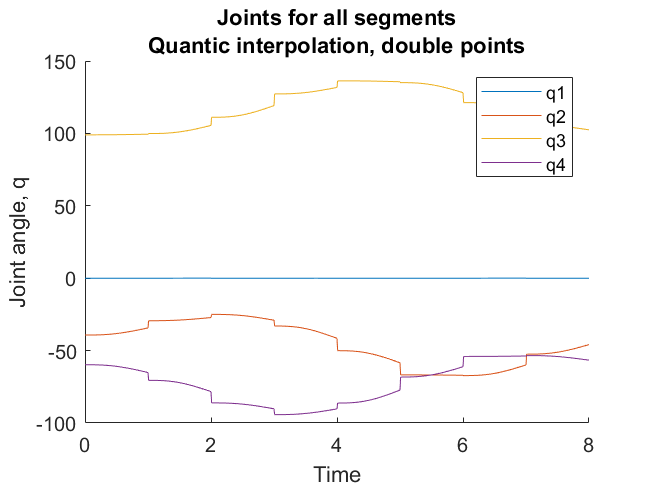

q4 = [q40A, q4A(2:end), q40B(2:end), q4B(2:end), q40C(2:end), q4C(2:end), q40D(2:end), q4D(2:end)];

t_all = 0:0.01:8;

figure 
hold on
plot(t_all,q1)
plot(t_all,q2)
plot(t_all,q3)
plot(t_all,q4)
xlabel("Time")
ylabel("Joint angle, q")
title(["Joints for all segments","Quantic interpolation, double points"])
legend(["q1","q2","q3","q4"])

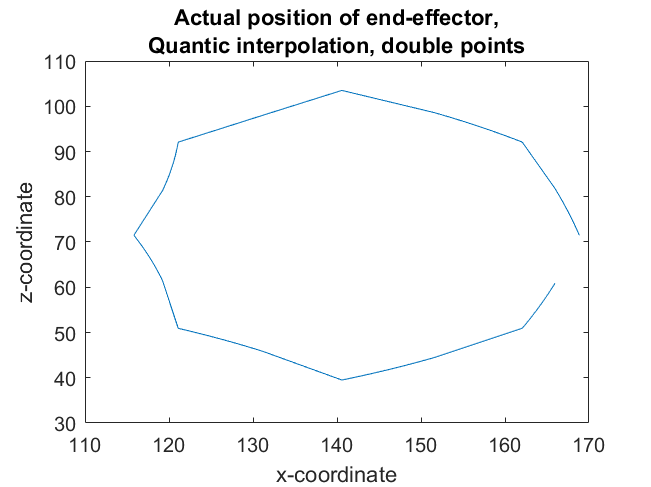



pos = zeros(4,length(q1));
for i = 1:length(pos)
    [T01, T12, T23, T34, T35] = T_finder(q1(i),q2(i),q3(i),q4(i));
    T04 = T01*T12*T23*T34;
    pos(:,i) = T04*[0,0,0,1]'; 
end

figure
plot(pos(1,:),pos(3,:))
title(["Actual position of end-effector,", "Quantic interpolation, double points"])
xlabel("x-coordinate")
ylabel("z-coordinate")

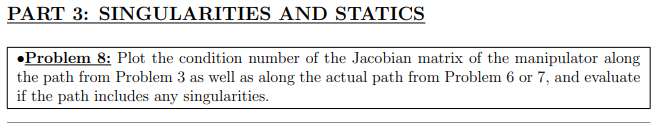

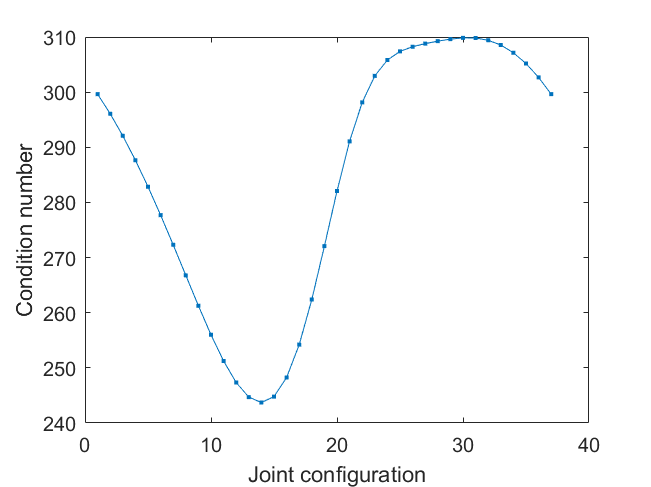


k=zeros(1,length(t1));
for i = 1:length(t1)
    [T01, T12, T23, T34, T35] = T_finder(t1(i),t2(i),t3(i),t4(i));
    J = Jacob(T01, T12, T23, T34); % Get jacobian at a given point
    k(i) = norm((J'*J)\J')*norm(J); % calculate the condition number
end
figure;
plot(k,'.-')
xlabel('Joint configuration')
ylabel('Condition number')

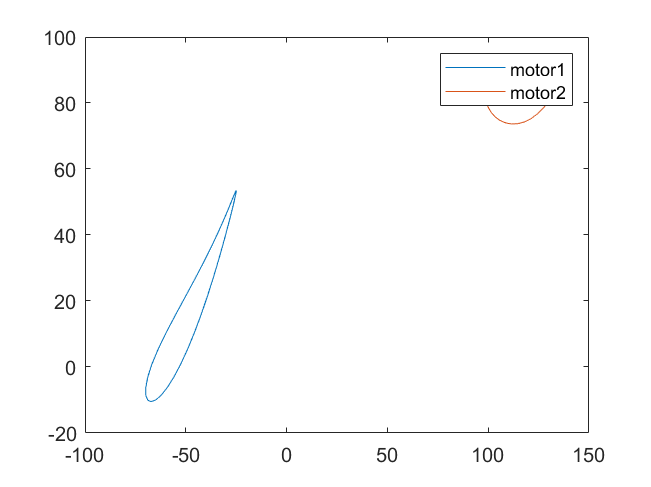

% this uses the collection of angles from problem 3
len = length(t1);
torque2 = zeros(1,len);
torque3 = zeros(1,len);
torque4 = zeros(1,len);

L12 = 93;
L23 = 93;
L34 = 50;
F = 1;

for i=1:len
    [torque2(i),torque3(i),torque4(i)] = torques(t2(i),t3(i),t4(i),1);



end

figure
plot(t2,torque2)
hold on

plot(t3,torque3)

%plot(t4,torque4)

legend(["motor1", "motor2"])%,"motor3"])


disp("Motor 4 is omitted here as the torques are smaller than")

Motor 4 is omitted here as the torques are smaller than


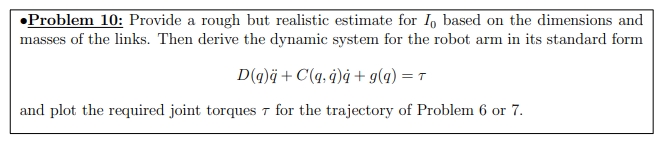

m = 0.2 % 200 g

m = 0.2000

a = 40;c = 50;b = [L01,L12,L23,L34]

b =     50    93    93    50



%Calculate the Inertia matrices
Ixx = m/12*(b.^2+c^2)

Ixx =    83.3333  185.8167  185.8167   83.3333


Iyy = m/12*(a^2+c^2)

Iyy = 68.3333

Izz = m/12*(a^2+b.^2)

Izz =    68.3333  170.8167  170.8167   68.3333



%Finding the rotional matrices from forward kinematics with respect to link
%center

syms theta0 theta1 theta2 theta3 I0 g;
L01 = 50;
L12 = 93;
L23 = 93;
L34 = 50;
L45 = 45;
L35 = 35;
H01 = 20;
H12 = 30;
H23 = 30;
H34 = 25;
T01 = sym([cos(theta0), 0, sin(theta0), 0;
       sin(theta0), 0, -cos(theta0), 0;
       0, 1, 0, L01;
       0, 0, 0, 1]);

T12 = sym([cos(theta1), -sin(theta1), 0, L12*cos(theta1);
       sin(theta1), cos(theta1), 0, L12*sin(theta1);
       0, 0, 1, 0;
       0, 0, 0, 1]);

T23 = sym([cos(theta2), -sin(theta2), 0, L23*cos(theta2);
       sin(theta2), cos(theta2), 0, L23*sin(theta2);
       0, 0, 1, 0;
       0, 0, 0, 1]);

T34 = sym([cos(theta3), -sin(theta3), 0, L34*cos(theta3);
       sin(theta3), cos(theta3), 0, L34*sin(theta3);
       0, 0, 1, 0;
       0, 0, 0, 1]);
m1 = 60;
m2 = 80;
m3 = 80;
m4 = 40;
J11=Jacob(T01, zeros(4,4), zeros(4,4), zeros(4,4));
J22=Jacob(T01, T12, zeros(4,4), zeros(4,4));
J33=Jacob(T01, T12, T23, zeros(4,4));
J44=Jacob(T01, T12, T23, T34);
D1 = sym([I0 0 0; 0 0.4*I0 0; 0 0 0.9*I0]);
D2 = sym([0.45*I0 0 0; 0 1.4*I0 0; 0 0 1.2*I0]);
D3 = sym([0.45*I0 0 0; 0 1.4*I0 0; 0 0 1.2*I0]);
D4 = sym([0.5*I0 0 0; 0 0.5*I0 0; 0 0 0.5*I0]);
M1 = sym([m1 0 0 0 0 0;
      0 m1 0 0 0 0;
      0 0 m1 0 0 0;
      0 0 0 D1(1,1) 0 0;
      0 0 0 0 D1(1,2) 0;
      0 0 0 0 0 D1(3,3)]);
M2 = sym([m2 0 0 0 0 0;
      0 m2 0 0 0 0;
      0 0 m2 0 0 0;
      0 0 0 D2(1,1) 0 0;
      0 0 0 0 D2(1,2) 0;
      0 0 0 0 0 D2(3,3)]);
M3 = sym([m3 0 0 0 0 0;
      0 m3 0 0 0 0;
      0 0 m3 0 0 0;
      0 0 0 D3(1,1) 0 0;
      0 0 0 0 D3(1,2) 0;
      0 0 0 0 0 D3(3,3)]);
M4 = sym([m4 0 0 0 0 0;
      0 m4 0 0 0 0;
      0 0 m4 0 0 0;
      0 0 0 D4(1,1) 0 0;
      0 0 0 0 D4(1,2) 0;
      0 0 0 0 0 D4(3,3)]);
D = J11'*M1*J11 + J22'*M2*J22 + J33'*M3*J33 + J44'*M4*J44;
C = sym(zeros(4,4,4));
C(1,1,1) = 1/2 * (diff(D(1,1),theta0)+diff(D(1,1),theta0)-diff(D(1,1),theta0));
C(1,1,2) = 1/2 * (diff(D(2,1),theta0)+diff(D(2,1),theta0)-diff(D(1,1),theta1));
C(1,1,3) = 1/2 * (diff(D(3,1),theta0)+diff(D(3,1),theta0)-diff(D(1,1),theta2));
C(1,1,4) = 1/2 * (diff(D(4,1),theta0)+diff(D(4,1),theta0)-diff(D(1,1),theta3));

C(1,2,1) = 1/2 * (diff(D(1,2),theta0)+diff(D(1,1),theta1)-diff(D(1,2),theta0));
C(1,2,2) = 1/2 * (diff(D(2,2),theta0)+diff(D(2,1),theta1)-diff(D(1,2),theta1));
C(1,2,3) = 1/2 * (diff(D(3,2),theta0)+diff(D(3,1),theta1)-diff(D(1,2),theta2));
C(1,2,4) = 1/2 * (diff(D(4,2),theta0)+diff(D(4,1),theta1)-diff(D(1,2),theta3));

C(1,3,1) = 1/2 * (diff(D(1,3),theta0)+diff(D(1,1),theta2)-diff(D(1,3),theta0));
C(1,3,2) = 1/2 * (diff(D(2,3),theta0)+diff(D(2,1),theta2)-diff(D(1,3),theta1));
C(1,3,3) = 1/2 * (diff(D(3,3),theta0)+diff(D(3,1),theta2)-diff(D(1,3),theta2));
C(1,3,4) = 1/2 * (diff(D(4,3),theta0)+diff(D(4,1),theta2)-diff(D(1,3),theta3));

C(1,4,1) = 1/2 * (diff(D(1,4),theta0)+diff(D(1,1),theta3)-diff(D(1,4),theta0));
C(1,4,1) = 1/2 * (diff(D(2,4),theta0)+diff(D(2,1),theta3)-diff(D(1,4),theta1));
C(1,4,3) = 1/2 * (diff(D(3,4),theta0)+diff(D(3,1),theta3)-diff(D(1,4),theta2));
C(1,4,4) = 1/2 * (diff(D(4,4),theta0)+diff(D(4,1),theta3)-diff(D(1,4),theta3));

C(2,1,1) = 1/2 * (diff(D(1,1),theta1)+diff(D(1,2),theta0)-diff(D(2,1),theta0));
C(2,1,2) = 1/2 * (diff(D(2,1),theta1)+diff(D(2,2),theta0)-diff(D(2,1),theta1));
C(2,1,3) = 1/2 * (diff(D(3,1),theta1)+diff(D(3,2),theta0)-diff(D(2,1),theta2));
C(2,1,4) = 1/2 * (diff(D(4,1),theta1)+diff(D(4,2),theta0)-diff(D(2,1),theta3));

C(2,2,1) = 1/2 * (diff(D(1,2),theta1)+diff(D(1,2),theta1)-diff(D(2,2),theta0));
C(2,2,2) = 1/2 * (diff(D(2,2),theta1)+diff(D(2,2),theta1)-diff(D(2,2),theta1));
C(2,2,3) = 1/2 * (diff(D(3,2),theta1)+diff(D(3,2),theta1)-diff(D(2,2),theta2));
C(2,2,4) = 1/2 * (diff(D(4,2),theta1)+diff(D(4,2),theta1)-diff(D(2,2),theta3));

C(2,3,1) = 1/2 * (diff(D(1,3),theta1)+diff(D(1,2),theta2)-diff(D(2,3),theta0));
C(2,3,2) = 1/2 * (diff(D(2,3),theta1)+diff(D(2,2),theta2)-diff(D(2,3),theta1));
C(2,3,3) = 1/2 * (diff(D(3,3),theta1)+diff(D(3,2),theta2)-diff(D(2,3),theta2));
C(2,3,4) = 1/2 * (diff(D(4,3),theta1)+diff(D(4,2),theta2)-diff(D(2,3),theta3));

C(2,4,1) = 1/2 * (diff(D(1,4),theta1)+diff(D(1,2),theta3)-diff(D(2,4),theta0));
C(2,4,1) = 1/2 * (diff(D(2,4),theta1)+diff(D(2,2),theta3)-diff(D(2,4),theta1));
C(2,4,3) = 1/2 * (diff(D(3,4),theta1)+diff(D(3,2),theta3)-diff(D(2,4),theta2));
C(2,4,4) = 1/2 * (diff(D(4,4),theta1)+diff(D(4,2),theta3)-diff(D(2,4),theta3));

C(3,1,1) = 1/2 * (diff(D(1,1),theta2)+diff(D(1,3),theta2)-diff(D(3,1),theta0));
C(3,1,2) = 1/2 * (diff(D(2,1),theta2)+diff(D(2,3),theta2)-diff(D(3,1),theta1));
C(3,1,3) = 1/2 * (diff(D(3,1),theta2)+diff(D(3,3),theta2)-diff(D(3,1),theta2));
C(3,1,4) = 1/2 * (diff(D(4,1),theta2)+diff(D(4,3),theta2)-diff(D(3,1),theta3));

C(3,2,1) = 1/2 * (diff(D(1,2),theta2)+diff(D(1,3),theta1)-diff(D(3,2),theta0));
C(3,2,2) = 1/2 * (diff(D(2,2),theta2)+diff(D(2,3),theta1)-diff(D(3,2),theta1));
C(3,2,3) = 1/2 * (diff(D(3,2),theta2)+diff(D(3,3),theta1)-diff(D(3,2),theta2));
C(3,2,4) = 1/2 * (diff(D(4,2),theta2)+diff(D(4,3),theta1)-diff(D(3,2),theta3));

C(3,3,1) = 1/2 * (diff(D(1,3),theta2)+diff(D(1,3),theta2)-diff(D(3,3),theta0));
C(3,3,2) = 1/2 * (diff(D(2,3),theta2)+diff(D(2,3),theta2)-diff(D(3,3),theta1));
C(3,3,3) = 1/2 * (diff(D(3,3),theta2)+diff(D(3,3),theta2)-diff(D(3,3),theta2));
C(3,3,4) = 1/2 * (diff(D(4,3),theta2)+diff(D(4,3),theta2)-diff(D(3,3),theta3));

C(3,4,1) = 1/2 * (diff(D(1,4),theta2)+diff(D(1,3),theta3)-diff(D(3,4),theta0));
C(3,4,1) = 1/2 * (diff(D(2,4),theta2)+diff(D(2,3),theta3)-diff(D(3,4),theta1));
C(3,4,3) = 1/2 * (diff(D(3,4),theta2)+diff(D(3,3),theta3)-diff(D(3,4),theta2));
C(3,4,4) = 1/2 * (diff(D(4,4),theta2)+diff(D(4,3),theta3)-diff(D(3,4),theta3));

C(4,1,1) = 1/2 * (diff(D(1,1),theta3)+diff(D(1,4),theta0)-diff(D(4,1),theta0));
C(4,1,2) = 1/2 * (diff(D(2,1),theta3)+diff(D(2,4),theta0)-diff(D(4,1),theta1));
C(4,1,3) = 1/2 * (diff(D(3,1),theta3)+diff(D(3,4),theta0)-diff(D(4,1),theta2));
C(4,1,4) = 1/2 * (diff(D(4,1),theta3)+diff(D(4,4),theta0)-diff(D(4,1),theta3));

C(4,2,1) = 1/2 * (diff(D(1,2),theta3)+diff(D(1,4),theta1)-diff(D(4,2),theta0));
C(4,2,2) = 1/2 * (diff(D(2,2),theta3)+diff(D(2,4),theta1)-diff(D(4,2),theta1));
C(4,2,3) = 1/2 * (diff(D(3,2),theta3)+diff(D(3,4),theta1)-diff(D(4,2),theta2));
C(4,2,4) = 1/2 * (diff(D(4,2),theta3)+diff(D(4,4),theta1)-diff(D(4,2),theta3));

C(3,3,1) = 1/2 * (diff(D(1,3),theta3)+diff(D(1,4),theta2)-diff(D(4,3),theta0));
C(3,3,2) = 1/2 * (diff(D(2,3),theta3)+diff(D(2,4),theta2)-diff(D(4,3),theta1));
C(3,3,3) = 1/2 * (diff(D(3,3),theta3)+diff(D(3,4),theta2)-diff(D(4,3),theta2));
C(3,3,4) = 1/2 * (diff(D(4,3),theta3)+diff(D(4,4),theta2)-diff(D(4,3),theta3));

C(3,4,1) = 1/2 * (diff(D(1,4),theta3)+diff(D(1,4),theta3)-diff(D(4,4),theta0));
C(3,4,1) = 1/2 * (diff(D(2,4),theta3)+diff(D(2,4),theta3)-diff(D(4,4),theta1));
C(3,4,3) = 1/2 * (diff(D(3,4),theta3)+diff(D(3,4),theta3)-diff(D(4,4),theta2));
C(3,4,4) = 1/2 * (diff(D(4,4),theta3)+diff(D(4,4),theta3)-diff(D(4,4),theta3));

Cq=sym(zeros(4,4));
Cq(1,1) = C(1,1,1) + C(2,1,1) + C(3,1,1) + C(4,1,1);
Cq(1,2) = C(1,1,2) + C(2,1,2) + C(3,1,2) + C(4,1,2);
Cq(1,3) = C(1,1,3) + C(2,1,3) + C(3,1,3) + C(4,1,3);
Cq(1,4) = C(1,1,4) + C(2,1,4) + C(3,1,4) + C(4,1,4);

Cq(2,1) = C(1,2,1) + C(2,2,1) + C(3,2,1) + C(4,2,1);
Cq(2,2) = C(1,2,2) + C(2,2,2) + C(3,2,2) + C(4,2,2);
Cq(2,3) = C(1,2,3) + C(2,2,3) + C(3,2,3) + C(4,2,3);
Cq(2,4) = C(1,2,4) + C(2,2,4) + C(3,2,4) + C(4,2,4);

Cq(3,1) = C(1,3,1) + C(2,3,1) + C(3,3,1) + C(4,3,1);
Cq(3,2) = C(1,3,2) + C(2,3,2) + C(3,3,2) + C(4,3,2);
Cq(3,3) = C(1,3,3) + C(2,3,3) + C(3,3,3) + C(4,3,3);
Cq(3,4) = C(1,3,4) + C(2,3,4) + C(3,3,4) + C(4,3,4);

Cq(4,1) = C(1,4,1) + C(2,4,1) + C(3,4,1) + C(4,4,1);
Cq(4,2) = C(1,4,2) + C(2,4,2) + C(3,4,2) + C(4,4,2);
Cq(4,3) = C(1,4,3) + C(2,4,3) + C(3,4,3) + C(4,4,3);
Cq(4,4) = C(1,4,4) + C(2,4,4) + C(3,4,4) + C(4,4,4);

P1 = m1*g*(L01-H01);
P2 = m2*g*((L01-H01)+sin(theta1)*(L12-H12));
P3 = m3*g*((L01-H01)+sin(theta1)*(L12-H12)+sin(theta2)*(L23-H23));
P4 = m4*g*((L01-H01)+sin(theta1)*(L12-H12)+sin(theta2)*(L23-H23)+sin(theta3)*(L34-H34));
P = P1 + P2 + P3 + P4;
G = sym(zeros(4,1));
G(1) = diff(P,theta0);
G(2) = diff(P,theta1);
G(3) = diff(P,theta2);
G(4) = diff(P,theta3);

Tao = D*qdotdot+Cq*qdot+G;